## Définition Fossen 2021 p.348

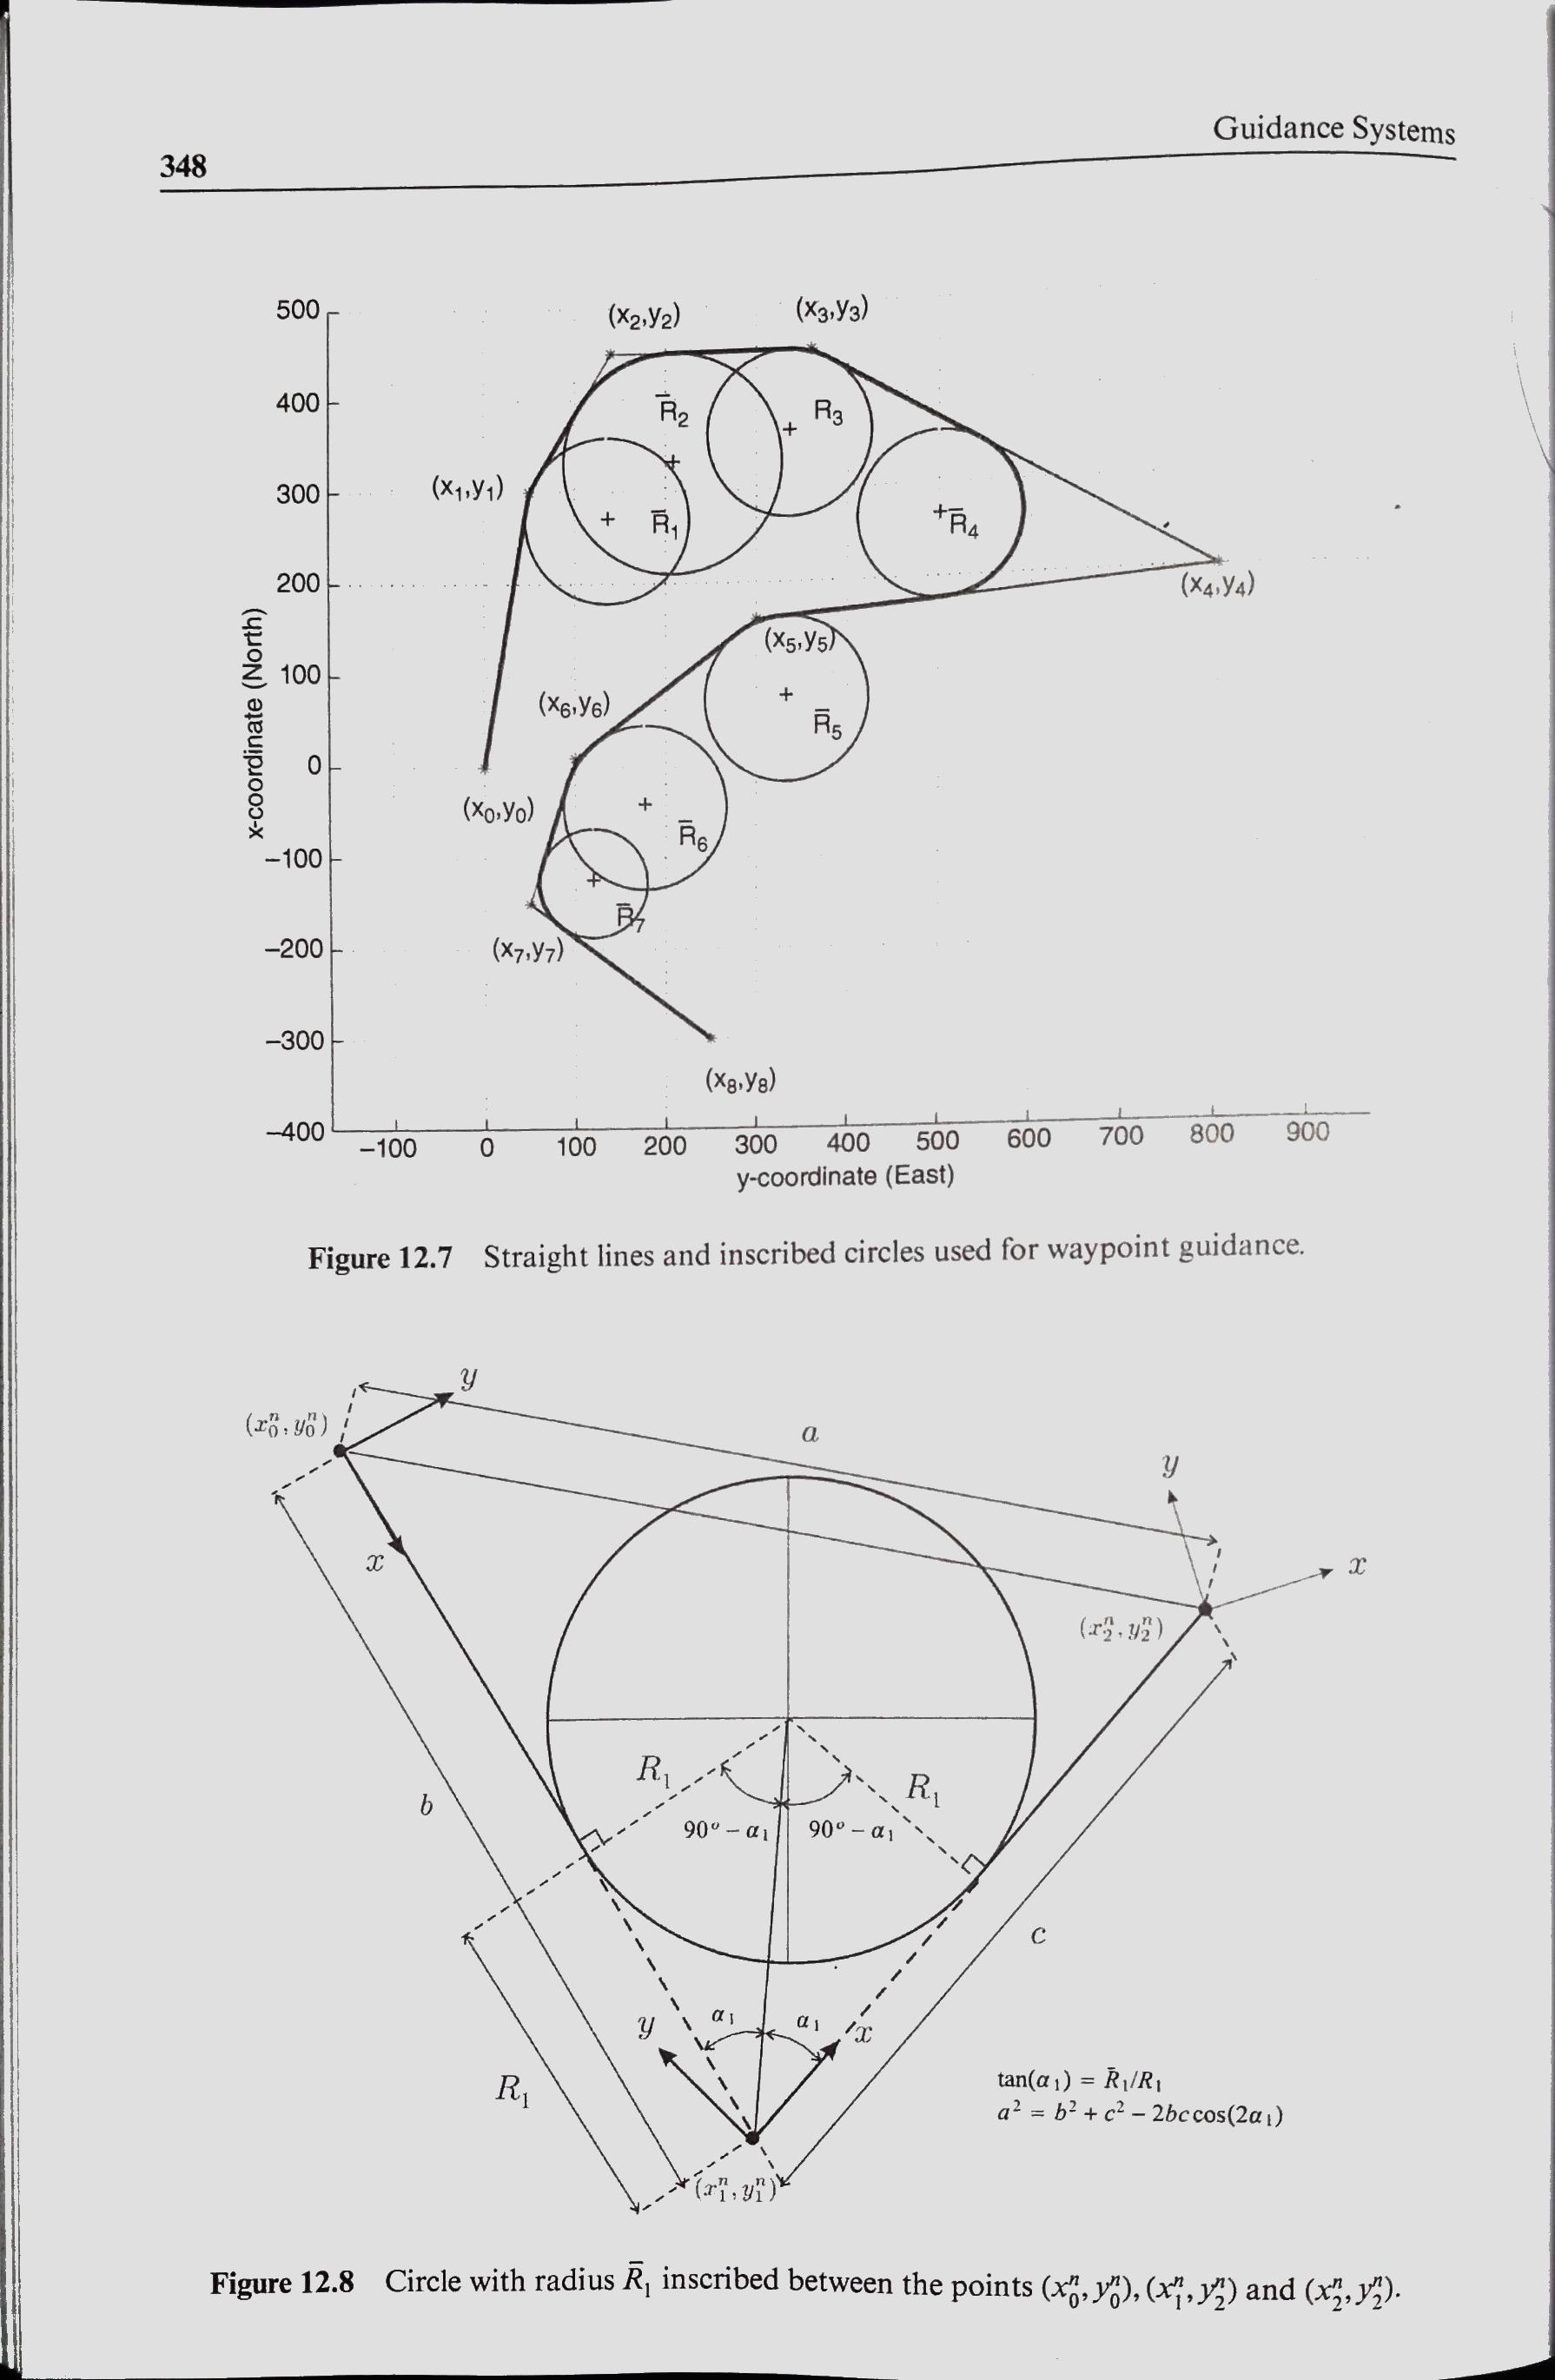

syms a b c alpha_1 R_1 R_bar_1

% Loi de cos
eqcos = a^2 == b^2 + c^2 - 2*b*c*cos(2*alpha_1)

$$eqcos = a^{2}=b^{2}-2\,\cos\left(2\,\alpha_{1}\right)\,b\,c+c^{2}$$


% eq triangle
eqtri = tan(alpha_1) == R_bar_1/R_1

$$eqtri = \tan\left(\alpha_{1}\right)=\frac{{\bar{R}}_{1}}{R_{1}}$$


eqa1 = isolate(eqtri,R_1)

$$eqa1 = R_{1}=\frac{{\bar{R}}_{1}}{\tan\left(\alpha_{1}\right)}$$


eqa2 = isolate(eqcos, alpha_1)

$$eqa2 = \alpha_{1}=\frac{\mathrm{acos}\left(\frac{-a^{2}+b^{2}+c^{2}}{2\,b\,c}\right)}{2}$$

## Exemple test

% Definition point.
     P0 = [0,0,0];
     P1 = [90,-10, -10];
     P2 = [100, 150, 50];
     R_bar = 200;

 % Determiner les vecteurs
    v02 = P2-P0

v02 =    100   150    50


    v01 = P1-P0

v01 =     90   -10   -10


    v12 = P2-P1

v12 =     10   160    60



 % Determiner les longeures du triangle
     a = norm(v02)

a = 187.0829

     b = norm(v01)

b = 91.1043

     c = norm(v12)

c = 171.1724


 % Calculer alpha 1
    alpha_1 = (1/2) * acos((-(a^2)+b^2+c^2)/(2*b*c)) % radians

alpha_1 = 0.7437


 % Calculer R
    R_1 = R_bar/tan(alpha_1)

R_1 = 217.4293


 % Calculer les points tangeant au cercle de rayon.
    p01 = P0 + (v01./b)* (b-R_1)

p01 =  -124.7937   13.8660   13.8660



    p12 = P1 + (v12./c)* R_1

p12 =   102.7024  193.2377   66.2141
